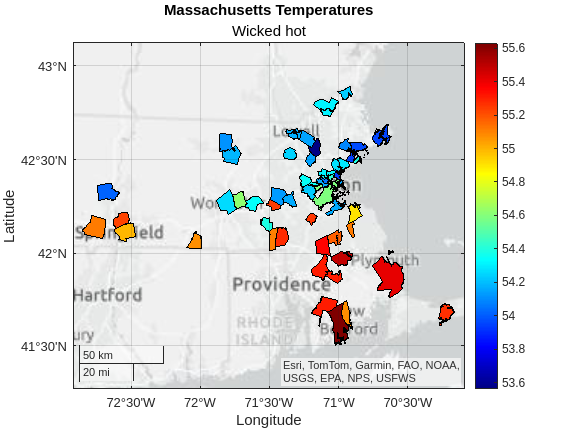

[data, stations] = simulateWeatherStations('10-01-2023', 10);
stations = categorical(upper(string(stations)));
data.MUNI = [categorical(upper(string({data.Station.MUNI})))]';
means = array2table(stations, "VariableNames","MUNI");
means.MUNI = upper(means.MUNI);
means.Temps = zeros(numel(stations),1);
for ii = 1:numel(stations)
    means.Temps(ii) = mean(data.Temp(data.MUNI == stations(ii)));
end
munis = readgeotable("townssurvey_shp/TOWNSSURVEY_POLY.shp");
munis.MUNI = categorical(munis.TOWN);

meansmunis = innerjoin(munis,means);
geoplot(meansmunis,ColorVariable="Temps");
colormap(jet);
colorbar;
title("Massachusetts Temperatures");
subtitle("Wicked hot");

data

data = 12960x6 table
          DateTime           Station      Temp    Humidity    Wind       MUNI    
    ____________________    __________    ____    ________    ____    ___________

    01-Oct-2023 01:00:00    1x1 struct     57       0.06       10     BOSTON     
    01-Oct-2023 01:00:00    1x1 struct     47       0.24        8     WORCESTER  
    01-Oct-2023 01:00:00    1x1 struct     50       0.12        6     SPRINGFIELD
    01-Oct-2023 01:00:00    1x1 struct     51       0.15        4     CAMBRIDGE  
    01-Oct-2023 01:00:00    1x1 struct     56       0.05        4     LOWELL     
    01-Oct-2023 01:00:00    1x1 struct     56       0.06        4     BROCKTON   
    01-Oct-2023 01:00:00    1x1 struct     48       0.18        3     NEW BEDFORD
    01-Oct-2023 01:00:00    1x1 stru